**Analysis of Combustion Model: Fitting to Mass fraction burned and fitting to Heat Release Rate**

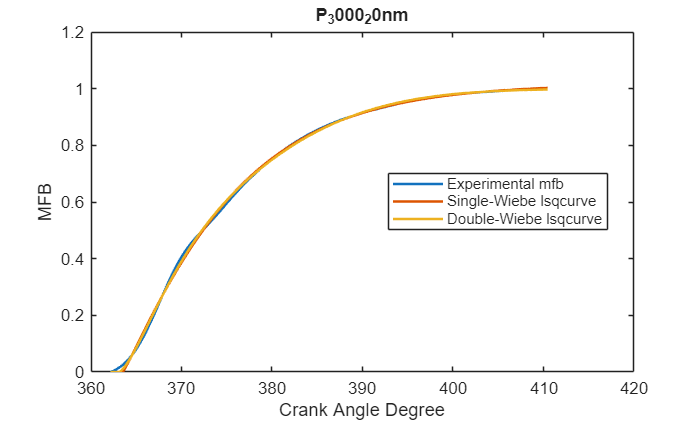

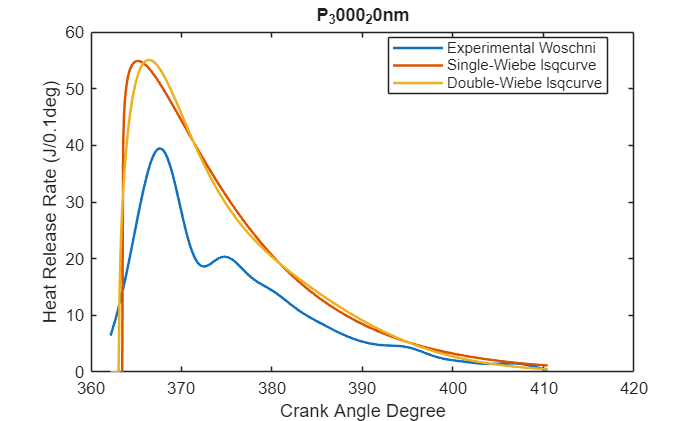

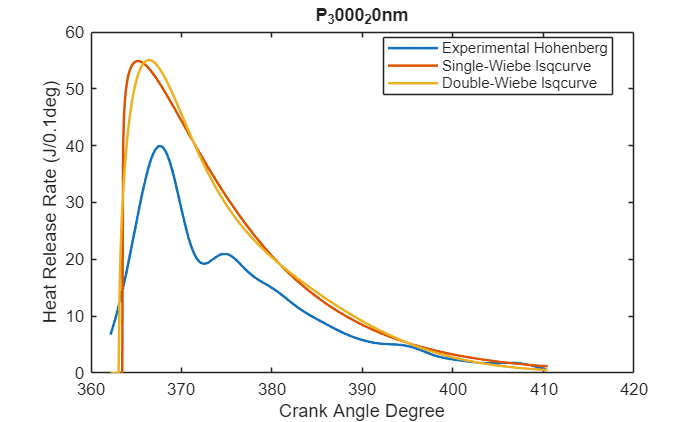

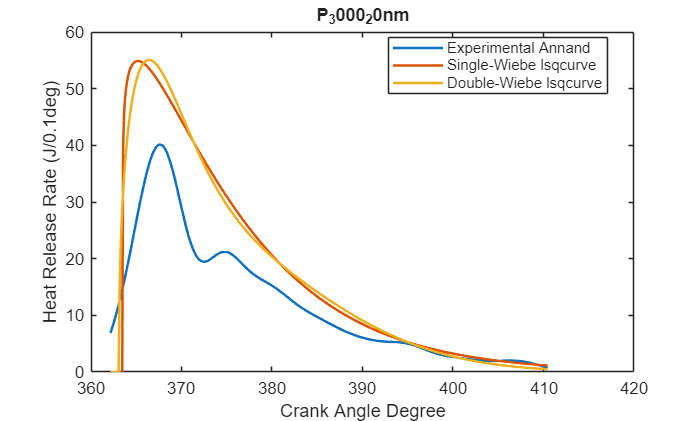

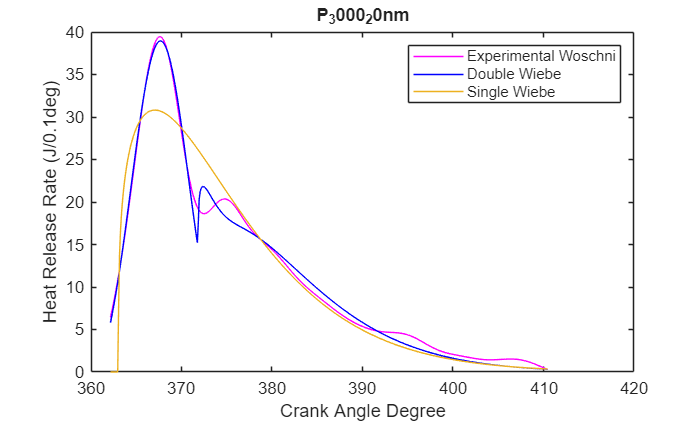

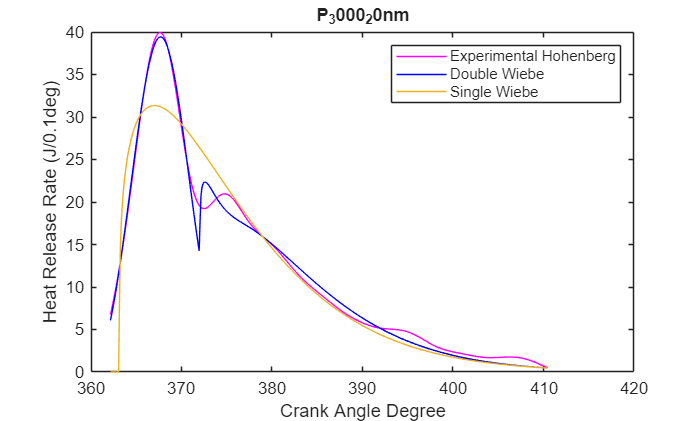

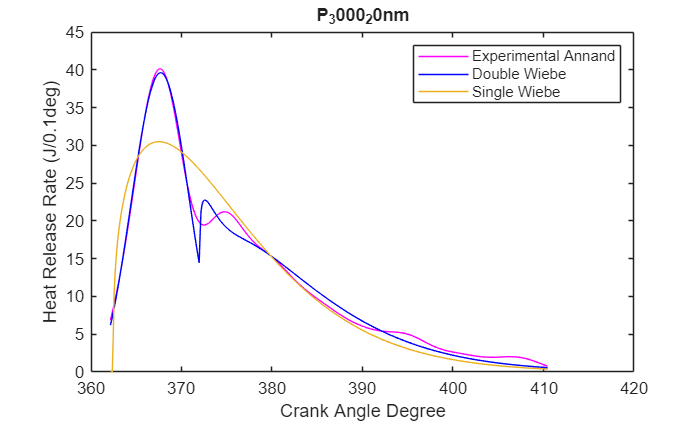

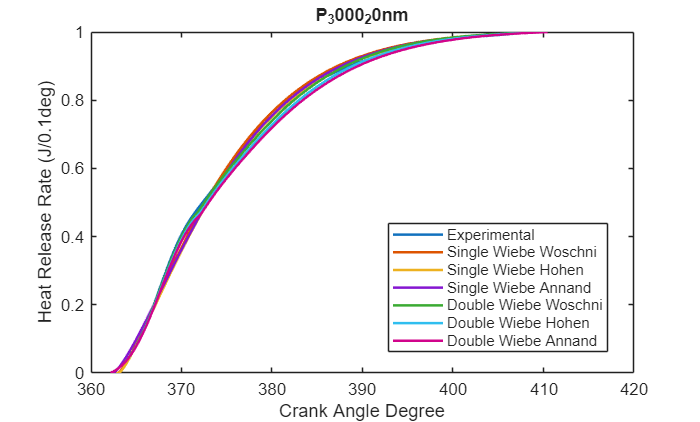

%In this script, 2 Wiebe function fitting procedures are analysed, i.e., fitting to mass fraction burned data and to experimental heat release rate
%data. The main objective is too determine which procedure provides the most accurate gross heat release rate estimations.

%The data used in this script is generated using the script, "Wiebe_comparison".
%----------------------------------------------------------------------------------------------------------------------------------------------------------

%Load example data that is generated using the script:Wiebe_comparison. The user must use their own data
load('Example_Data\combustion analysis\B20.mat');

% Define file-sheet combinations
    files_and_sheets = {
        '3000_20nm.xlsx', '3000_20nm';
        '3000_12nm.xlsx', '3000_12nm';
        '2500_20nm.xlsx', '2500_20nm';
        '2500_12nm.xlsx', '2500_12nm';
        '2500_5nm.xlsx', '2500_5nm';
        '2000_20nm.xlsx', '2000_20nm';
        '2000_12nm.xlsx', '2000_12nm';
        '2000_5nm.xlsx', '2000_5nm';
 };

for i=1:length(files_and_sheets)
    filename=files_and_sheets{i,1};

    %create variable name from filename
    [~,VarName,~]=fileparts(filename);
    VarName=matlab.lang.makeValidName(['P_' VarName]);

    %Plot Results due to fitting to xb data
    figure;
    plot(CAD.(VarName),Experimental_xb.(VarName), CAD.(VarName), Single_Wiebe_lsqcurve_fit.(VarName), CAD.(VarName),Double_Wiebe_lsqcurve_fit.(VarName), LineWidth=1.5)
    xlabel('Crank Angle Degree')
    ylabel("MFB")
    legend('Experimental mfb', 'Single-Wiebe lsqcurve', 'Double-Wiebe lsqcurve','Location','best' )
    title(VarName);


    figure;
    plot(CAD.(VarName),dQ_Woschni.(VarName), CAD.(VarName),HRRSingle_Hel.(VarName), CAD.(VarName),HRRDouble_Hel.(VarName), LineWidth=1.5)
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    legend('Experimental Woschni', 'Single-Wiebe lsqcurve', 'Double-Wiebe lsqcurve','Location','best' )
    title(VarName);

    figure;
    plot(CAD.(VarName),dQ_Hohenberg.(VarName), CAD.(VarName),HRRSingle_Hel.(VarName), CAD.(VarName),HRRDouble_Hel.(VarName), LineWidth=1.5)
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    legend('Experimental Hohenberg', 'Single-Wiebe lsqcurve', 'Double-Wiebe lsqcurve','Location','best' )
    title(VarName);

    figure;
    plot(CAD.(VarName),dQ_Annand.(VarName), CAD.(VarName),HRRSingle_Hel.(VarName), CAD.(VarName),HRRDouble_Hel.(VarName), LineWidth=1.5)
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    legend('Experimental Annand', 'Single-Wiebe lsqcurve', 'Double-Wiebe lsqcurve','Location','best' )
    title(VarName);

    %Plot of single and double wiebe HRR - Woschni
    figure;
    plot(CAD.(VarName),dQ_Woschni.(VarName), 'm-'); 
    hold on;
    plot(CAD.(VarName),SumHRR_Woschni.(VarName), 'b-')
    plot(CAD.(VarName),HRRSingle_W.(VarName), '-')
    legend('Experimental Woschni', 'Double Wiebe','Single Wiebe')
    hold off;
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    title(VarName);

    %Plot of single and double wiebe HRR -Hohenberg
    figure;
    plot(CAD.(VarName),dQ_Hohenberg.(VarName), 'm-'); 
    hold on;
    plot(CAD.(VarName),SumHRR_Hohen.(VarName), 'b-')
    plot(CAD.(VarName),HRRSingle_H.(VarName), '-')
    legend('Experimental Hohenberg', 'Double Wiebe','Single Wiebe')
    hold off;
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    title(VarName);

    %Plot of single and double wiebe HRR - Annand
    figure;
    plot(CAD.(VarName),dQ_Annand.(VarName), 'm-'); 
    hold on;
    plot(CAD.(VarName),SumHRR_Annand.(VarName), 'b-')
    plot(CAD.(VarName),HRRSingle_A.(VarName), '-')
    legend('Experimental Annand', 'Double Wiebe','Single Wiebe')
    hold off;
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    title(VarName);

    %Plot of mfb calculated from single and double wiebe HRR
    figure;
    plot(CAD.(VarName),Experimental_xb.(VarName), CAD.(VarName), xbW.(VarName), CAD.(VarName),xbH.(VarName), CAD.(VarName),xbA.(VarName),  CAD.(VarName),xbdW.(VarName),  CAD.(VarName),xbdH.(VarName),  CAD.(VarName),xbdA.(VarName), LineWidth=1.5)
    xlabel('Crank Angle Degree')
    ylabel("Heat Release Rate (J/0.1deg)")
    legend('Experimental', 'Single Wiebe Woschni','Single Wiebe Hohen','Single Wiebe Annand','Double Wiebe Woschni','Double Wiebe Hohen','Double Wiebe Annand','Location','best')
    title(VarName);

end

Wiebe Analysis

data_mfb_RMSE.P_2000_5nm

ans = 2×4 table
                     RMSE_xb     RMSE_xb_Woschni_HRR    RMSE_xb_Hohenberg_HRR    RMSE_xb_Annand_HRR
                    _________    ___________________    _____________________    __________________

    Single_Wiebe     0.012773           20.05                  19.695                  19.571      
    Double_Wiebe    0.0029319          18.439                  18.055                   17.92      


data_mfb_RMSE.P_2000_12nm

ans = 2×4 table
                     RMSE_xb     RMSE_xb_Woschni_HRR    RMSE_xb_Hohenberg_HRR    RMSE_xb_Annand_HRR
                    _________    ___________________    _____________________    __________________

    Single_Wiebe     0.012895          21.307                  20.936                  20.807      
    Double_Wiebe    0.0050984          19.129                  18.716                  18.574      


data_mfb_RMSE.P_2000_12nm{1,1}

ans = 0.0129

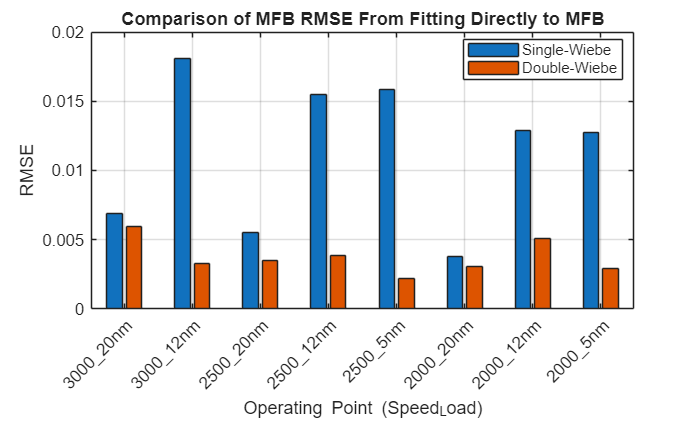


operating_points = {'3000\_20nm','3000\_12nm', ...
                    '2500\_20nm','2500\_12nm','2500\_5nm', ...
                    '2000\_20nm','2000\_12nm','2000\_5nm'};

RMSE1 = [data_mfb_RMSE.P_3000_20nm{1,1}, data_mfb_RMSE.P_3000_12nm{1,1}, data_mfb_RMSE.P_2500_20nm{1,1}, data_mfb_RMSE.P_2500_12nm{1,1}, data_mfb_RMSE.P_2500_5nm{1,1}, data_mfb_RMSE.P_2000_20nm{1,1},data_mfb_RMSE.P_2000_12nm{1,1},data_mfb_RMSE.P_2000_5nm{1,1}];
RMSE2 = [data_mfb_RMSE.P_3000_20nm{2,1}, data_mfb_RMSE.P_3000_12nm{2,1}, data_mfb_RMSE.P_2500_20nm{2,1}, data_mfb_RMSE.P_2500_12nm{2,1}, data_mfb_RMSE.P_2500_5nm{2,1}, data_mfb_RMSE.P_2000_20nm{2,1},data_mfb_RMSE.P_2000_12nm{2,1},data_mfb_RMSE.P_2000_5nm{2,1}];

% Combine into one matrix (each column = one data set)
RMSE_all_mfb = [RMSE1; RMSE2]';

% Plot one grouped bar chart
figure;
bar(RMSE_all_mfb)
set(gca, 'XTickLabel', operating_points, 'XTick', 1:numel(operating_points))
xtickangle(45)
xlabel('Operating Point (Speed_Load)')
ylabel('RMSE')
title('Comparison of MFB RMSE From Fitting Directly to MFB')
legend('Single-Wiebe','Double-Wiebe','Location','best')
grid on

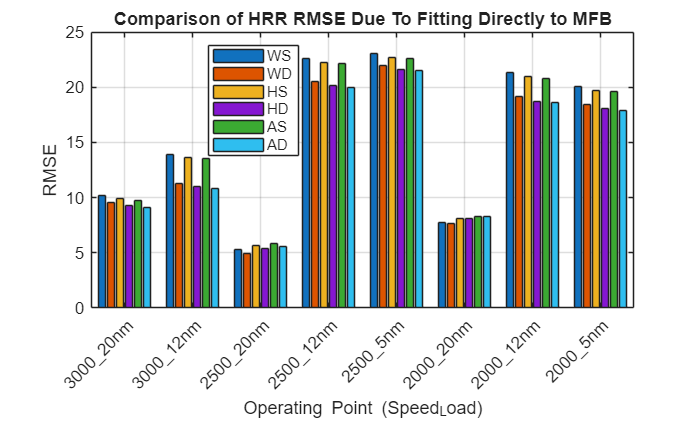

RMSEW1 = [data_mfb_RMSE.P_3000_20nm{1,2}, data_mfb_RMSE.P_3000_12nm{1,2},  data_mfb_RMSE.P_2500_20nm{1,2}, data_mfb_RMSE.P_2500_12nm{1,2}, data_mfb_RMSE.P_2500_5nm{1,2}, data_mfb_RMSE.P_2000_20nm{1,2},data_mfb_RMSE.P_2000_12nm{1,2},data_mfb_RMSE.P_2000_5nm{1,2}];
RMSEW2 = [data_mfb_RMSE.P_3000_20nm{2,2}, data_mfb_RMSE.P_3000_12nm{2,2},  data_mfb_RMSE.P_2500_20nm{2,2}, data_mfb_RMSE.P_2500_12nm{2,2}, data_mfb_RMSE.P_2500_5nm{2,2}, data_mfb_RMSE.P_2000_20nm{2,2},data_mfb_RMSE.P_2000_12nm{2,2},data_mfb_RMSE.P_2000_5nm{2,2}];

RMSEH1 = [data_mfb_RMSE.P_3000_20nm{1,3}, data_mfb_RMSE.P_3000_12nm{1,3},  data_mfb_RMSE.P_2500_20nm{1,3}, data_mfb_RMSE.P_2500_12nm{1,3}, data_mfb_RMSE.P_2500_5nm{1,3}, data_mfb_RMSE.P_2000_20nm{1,3},data_mfb_RMSE.P_2000_12nm{1,3},data_mfb_RMSE.P_2000_5nm{1,3}];
RMSEH2 = [data_mfb_RMSE.P_3000_20nm{2,3}, data_mfb_RMSE.P_3000_12nm{2,3},  data_mfb_RMSE.P_2500_20nm{2,3}, data_mfb_RMSE.P_2500_12nm{2,3}, data_mfb_RMSE.P_2500_5nm{2,3}, data_mfb_RMSE.P_2000_20nm{2,3},data_mfb_RMSE.P_2000_12nm{2,3},data_mfb_RMSE.P_2000_5nm{2,3}];

RMSEA1 = [data_mfb_RMSE.P_3000_20nm{1,4}, data_mfb_RMSE.P_3000_12nm{1,4},  data_mfb_RMSE.P_2500_20nm{1,4}, data_mfb_RMSE.P_2500_12nm{1,4}, data_mfb_RMSE.P_2500_5nm{1,4}, data_mfb_RMSE.P_2000_20nm{1,4},data_mfb_RMSE.P_2000_12nm{1,4},data_mfb_RMSE.P_2000_5nm{1,4}];
RMSEA2 = [data_mfb_RMSE.P_3000_20nm{2,4}, data_mfb_RMSE.P_3000_12nm{2,4},  data_mfb_RMSE.P_2500_20nm{2,4}, data_mfb_RMSE.P_2500_12nm{2,4}, data_mfb_RMSE.P_2500_5nm{2,4}, data_mfb_RMSE.P_2000_20nm{2,4},data_mfb_RMSE.P_2000_12nm{2,4},data_mfb_RMSE.P_2000_5nm{2,4}];

% Combine into one matrix (each column = one data set)
RMSE_all = [RMSEW1; RMSEW2; RMSEH1; RMSEH2; RMSEA1; RMSEA2]';

% Plot one grouped bar chart
figure;
bar(RMSE_all)
set(gca, 'XTickLabel', operating_points, 'XTick', 1:numel(operating_points))
xtickangle(45)
xlabel('Operating Point (Speed_Load)')
ylabel('RMSE')
title('Comparison of HRR RMSE Due To Fitting Directly to MFB')
legend('WS','WD','HS','HD','AS','AD','Location','best')
grid on

RMSE_HRR.P_2000_5nm

ans = 2×3 table
                    Woschni    Hohenberg    Annand 
                    _______    _________    _______

    Double_Wiebe    0.52996     0.57726     0.60672
    Single_Wiebe     3.4052      3.5059      3.5561


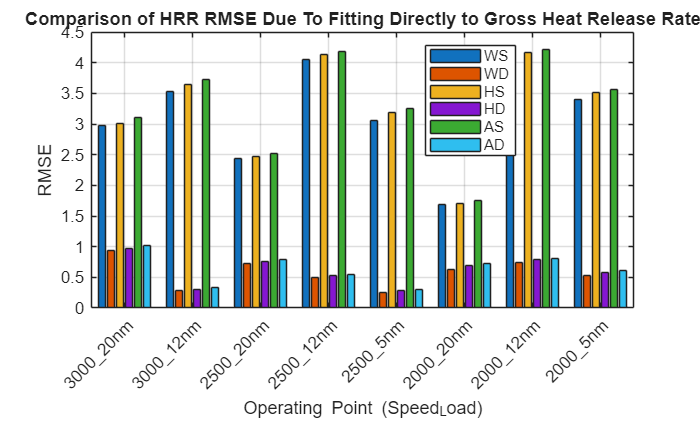

RMSEW2_HRR = [RMSE_HRR.P_3000_20nm{1,1}, RMSE_HRR.P_3000_12nm{1,1},  RMSE_HRR.P_2500_20nm{1,1}, RMSE_HRR.P_2500_12nm{1,1}, RMSE_HRR.P_2500_5nm{1,1}, RMSE_HRR.P_2000_20nm{1,1},RMSE_HRR.P_2000_12nm{1,1},RMSE_HRR.P_2000_5nm{1,1}];
RMSEW1_HRR = [RMSE_HRR.P_3000_20nm{2,1}, RMSE_HRR.P_3000_12nm{2,1},  RMSE_HRR.P_2500_20nm{2,1}, RMSE_HRR.P_2500_12nm{2,1}, RMSE_HRR.P_2500_5nm{2,1}, RMSE_HRR.P_2000_20nm{2,1},RMSE_HRR.P_2000_12nm{2,1},RMSE_HRR.P_2000_5nm{2,1}];

RMSEH2_HRR = [RMSE_HRR.P_3000_20nm{1,2}, RMSE_HRR.P_3000_12nm{1,2},  RMSE_HRR.P_2500_20nm{1,2}, RMSE_HRR.P_2500_12nm{1,2}, RMSE_HRR.P_2500_5nm{1,2}, RMSE_HRR.P_2000_20nm{1,2},RMSE_HRR.P_2000_12nm{1,2},RMSE_HRR.P_2000_5nm{1,2}];
RMSEH1_HRR = [RMSE_HRR.P_3000_20nm{2,2}, RMSE_HRR.P_3000_12nm{2,2},  RMSE_HRR.P_2500_20nm{2,2}, RMSE_HRR.P_2500_12nm{2,2}, RMSE_HRR.P_2500_5nm{2,2}, RMSE_HRR.P_2000_20nm{2,2},RMSE_HRR.P_2000_12nm{2,2},RMSE_HRR.P_2000_5nm{2,2}];

RMSEA2_HRR = [RMSE_HRR.P_3000_20nm{1,3}, RMSE_HRR.P_3000_12nm{1,3},  RMSE_HRR.P_2500_20nm{1,3}, RMSE_HRR.P_2500_12nm{1,3}, RMSE_HRR.P_2500_5nm{1,3}, RMSE_HRR.P_2000_20nm{1,3},RMSE_HRR.P_2000_12nm{1,3},RMSE_HRR.P_2000_5nm{1,3}];
RMSEA1_HRR = [RMSE_HRR.P_3000_20nm{2,3}, RMSE_HRR.P_3000_12nm{2,3},  RMSE_HRR.P_2500_20nm{2,3}, RMSE_HRR.P_2500_12nm{2,3}, RMSE_HRR.P_2500_5nm{2,3}, RMSE_HRR.P_2000_20nm{2,3},RMSE_HRR.P_2000_12nm{2,3},RMSE_HRR.P_2000_5nm{2,3}];


% Combine into one matrix (each column = one data set)
RMSE_all_HRR = [RMSEW1_HRR; RMSEW2_HRR; RMSEH1_HRR; RMSEH2_HRR; RMSEA1_HRR; RMSEA2_HRR]';

% Plot one grouped bar chart
figure;
bar(RMSE_all_HRR)
set(gca, 'XTickLabel', operating_points, 'XTick', 1:numel(operating_points))
xtickangle(45)
xlabel('Operating Point (Speed_Load)')
ylabel('RMSE')
title('Comparison of HRR RMSE Due To Fitting Directly to Gross Heat Release Rate')
legend('WS','WD','HS','HD','AS','AD','Location','best')
grid on

RMSE_mfb_HRR.P_2000_5nm

ans = 2×3 table
                     Woschni      Hohen       Annand 
                    _________    ________    ________

    Single_Wiebe      0.02681    0.021297    0.019616
    Double_Wiebe    0.0078393    0.015714    0.019098


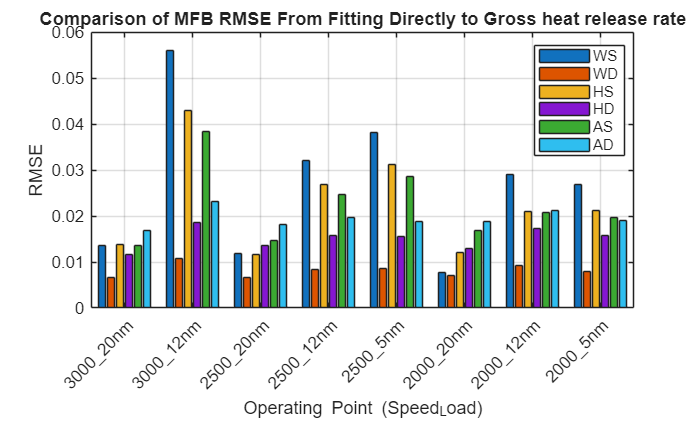

RMSEW1_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{1,1}, RMSE_mfb_HRR.P_3000_12nm{1,1},  RMSE_mfb_HRR.P_2500_20nm{1,1}, RMSE_mfb_HRR.P_2500_12nm{1,1}, RMSE_mfb_HRR.P_2500_5nm{1,1}, RMSE_mfb_HRR.P_2000_20nm{1,1},RMSE_mfb_HRR.P_2000_12nm{1,1},RMSE_mfb_HRR.P_2000_5nm{1,1}];
RMSEW2_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{2,1}, RMSE_mfb_HRR.P_3000_12nm{2,1},  RMSE_mfb_HRR.P_2500_20nm{2,1}, RMSE_mfb_HRR.P_2500_12nm{2,1}, RMSE_mfb_HRR.P_2500_5nm{2,1}, RMSE_mfb_HRR.P_2000_20nm{2,1},RMSE_mfb_HRR.P_2000_12nm{2,1},RMSE_mfb_HRR.P_2000_5nm{2,1}];

RMSEH1_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{1,2}, RMSE_mfb_HRR.P_3000_12nm{1,2},  RMSE_mfb_HRR.P_2500_20nm{1,2}, RMSE_mfb_HRR.P_2500_12nm{1,2}, RMSE_mfb_HRR.P_2500_5nm{1,2}, RMSE_mfb_HRR.P_2000_20nm{1,2},RMSE_mfb_HRR.P_2000_12nm{1,2},RMSE_mfb_HRR.P_2000_5nm{1,2}];
RMSEH2_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{2,2}, RMSE_mfb_HRR.P_3000_12nm{2,2},  RMSE_mfb_HRR.P_2500_20nm{2,2}, RMSE_mfb_HRR.P_2500_12nm{2,2}, RMSE_mfb_HRR.P_2500_5nm{2,2}, RMSE_mfb_HRR.P_2000_20nm{2,2},RMSE_mfb_HRR.P_2000_12nm{2,2},RMSE_mfb_HRR.P_2000_5nm{2,2}];

RMSEA1_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{1,3}, RMSE_mfb_HRR.P_3000_12nm{1,3},  RMSE_mfb_HRR.P_2500_20nm{1,3}, RMSE_mfb_HRR.P_2500_12nm{1,3}, RMSE_mfb_HRR.P_2500_5nm{1,3}, RMSE_mfb_HRR.P_2000_20nm{1,3},RMSE_mfb_HRR.P_2000_12nm{1,3},RMSE_mfb_HRR.P_2000_5nm{1,3}];
RMSEA2_HRR_MFB = [RMSE_mfb_HRR.P_3000_20nm{2,3}, RMSE_mfb_HRR.P_3000_12nm{2,3},  RMSE_mfb_HRR.P_2500_20nm{2,3}, RMSE_mfb_HRR.P_2500_12nm{2,3}, RMSE_mfb_HRR.P_2500_5nm{2,3}, RMSE_mfb_HRR.P_2000_20nm{2,3},RMSE_mfb_HRR.P_2000_12nm{2,3},RMSE_mfb_HRR.P_2000_5nm{2,3}];

% Combine into one matrix (each column = one data set)
RMSE_all_HRR = [RMSEW1_HRR_MFB; RMSEW2_HRR_MFB; RMSEH1_HRR_MFB; RMSEH2_HRR_MFB; RMSEA1_HRR_MFB; RMSEA2_HRR_MFB]';

% Plot one grouped bar chart
figure;
bar(RMSE_all_HRR)
set(gca, 'XTickLabel', operating_points, 'XTick', 1:numel(operating_points))
xtickangle(45)
xlabel('Operating Point (Speed_Load)')
ylabel('RMSE')
title('Comparison of MFB RMSE From Fitting Directly to Gross heat release rate')
legend('WS','WD','HS','HD','AS','AD','Location','best')
grid on